# This code plots the data as shown in Figure 2

Kristen Fogaren [fogaren@bc.edu](mailto:fogaren@bc.edu)

Assumes the data has been downloaded using M2M_Data_Figure2.m and saved

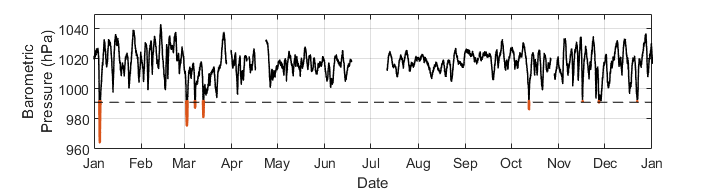

load CP03ISSMmetpackage.mat 

% Pulls out the pressure data (mbar) and finds values below 3 times the standard deviation of the mean
pres_mbar = metbk_variables(7).data;
ind_under = find(pres_mbar < nanmean(pres_mbar) - 3*nanstd(pres_mbar));

% Figure shows data for 2018. Replicates Figure 2 

% Pressure threshold calculated for for 2014 thru 8/2020
%th = nanmean(pres_mbar) - 3*nanstd(pres_mbar); % Commented out because
%downloaded data is only for 2018 b/c of online space storage issues 
th = 991.14; % This is correct threshold (2014-2020 calc)
red = [0.85098 0.32549 0.098039]; % Color for plot

figure
% sets up figure properties 
fig = gcf;
set(fig, 'Color', 'w');
set(fig,'units','inches','position',[.5 .5 7.5 2])
set(0,'defaultaxesfontsize',12);
set(0,'defaulttextfontsize',12);
% Plots data and highlights data below threshold
plot(metbk_mtime,pres_mbar,'.k','MarkerSize',3.5)
hold on
plot(metbk_mtime(ind_under),pres_mbar(ind_under),'.','Color',red)
plot(metbk_mtime,ones(1,length(pres_mbar))*th,'k--') % Creates dashed line at threshold 
% Sets timeframe and tickmark locations 
startDate = datenum(2018,01,01,00,00,00); endDate = datenum(2019,01,01,00,00,00);
mon = ['2018,01,01'; '2018,02,01'; '2018,03,01'; '2018,04,01';...
    '2018,05,01'; '2018,06,01';'2018,07,01';'2018,08,01';'2018,09,01';'2018,10,01';...
    '2018,11,01';'2018,12,01';'2019,01,01'];
ax = gca; ax.XTick = datenum(mon);
ylim([960 1050])
ylabel({'Barometric';'Pressure (hPa)'},'FontName','Arial')
datetick('x','mmm','KeepLimits','KeepTicks')
xlabel('Date')
xlim([startDate datenum(2019,01,01,00,00,00)])
grid on